# **Matisse example for Mouse Brain (MERFISH)**

Addding the second file in SPOTS2. In this case we do not need it, because we work with 1 sample

decoded_file = 'G:\MATISSE\data\MERFISH\barcodes_287gene_0103_hMTG.csv';
image = 'G:\MATISSE\data\MERFISH\mosaic_287gene_0103_hMTG.tif';    % important for size
barcodes='G:\MATISSE\data\MERFISH\hMTGE_barcode_id_to_geneName_conversion.csv';
scale=0.33; %
%% do not modify
% load
SPOTS2=MERFISH_getspots(decoded_file,barcodes);
SPOTS2.image=image;
SPOTS2.scale=scale;



Add third file in SPOTS3

% decoded_file = 'G:\MATISSE\data\mousebrain\ISS_3_spot_table.csv';
% image = 'G:\MATISSE\data\mousebrain\HCA_11_3_m_133_c1-1.tif';    % important for size
% scale=1/0.163; %
% %% do not modify
% % load
% SPOTS3=ISS_getspots(decoded_file);
% SPOTS3.image=image;
% SPOTS3.scale=scale;



And then we combine them into a big object (note that if you have added more samples you need to add them here as well)

%ALLSPOTS.SPOTS1=SPOTS1;
ALLSPOTS.SPOTS2=SPOTS2;
%ALLSPOTS.SPOTS3=SPOTS3;

### **Format ALLSSPOTS in good format**

We use 'fill_matisse' to format the ALLSPOTS in the SPOTS object. 

SPOTS=fill_matisse(ALLSPOTS);

## **Basic plotsfunction**

We plot the GeneDensity of 1 gene

show_spots(SPOTS);
unique(SPOTS.spotname)
SPOTS.Genes_of_interest={'Wasf1'}
SPOTS.bandwidth=800;
SPOTS=GeneDensity(SPOTS);


**Overlay densities**

In this case we overlay two densities

SPOTS.bandwidth=30;
SPOTS.Genes_of_interest={'FAM46A','SDK1'}

SPOTS =   matisse with properties:

                Graphics: 1
                spotname: {1824196×1 cell}
                location: [1824196×2 double]
                  sample: {1824196×1 cell}
               sample_ID: []
                  images: {'G:\MATISSE\data\MERFISH\mosaic_287gene_0103_hMTG.tif'}
                   scale: {[0.3300]}
        expressionmatrix: []
         expressionnames: []
             centroidpos: {}
                Cellmaps: {}
              centroidID: {}
               bandwidth: 30
             hexbin_size: 20
                  radius: 100
                distance: 100
       Genes_of_interest: {'FAM46A'  'SDK1'}
                colormap: [256×3 double]
         count_threshold: 1
    segmentation_percent: 95
           Clustering_ID: []
                RGB_CODE: []
         UMAP_clustering: []
       pciseq_clustering: []
                   limit: 800
        CellCallRegionYX: []
           

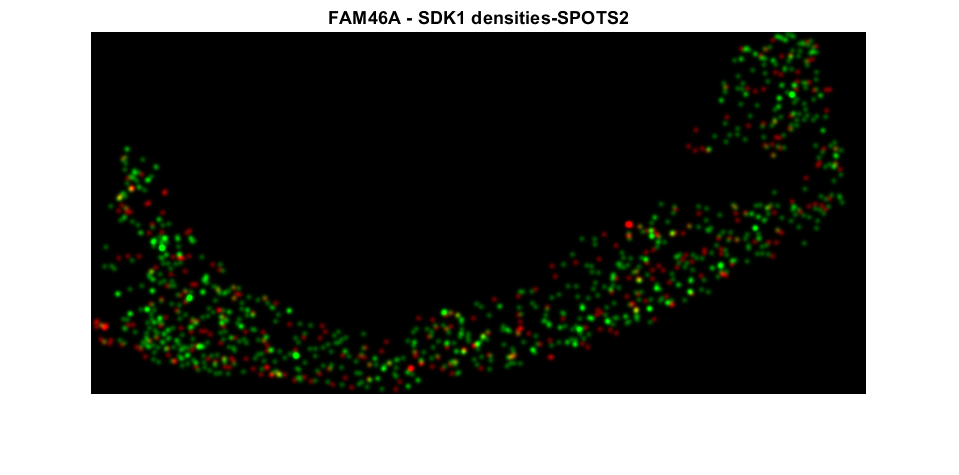

SPOTS=OverlayTwoDensities(SPOTS);

Run the dissimilarity test, for each sample on the section. Varargin 1 is threshold and varargin 2 is bin size. 

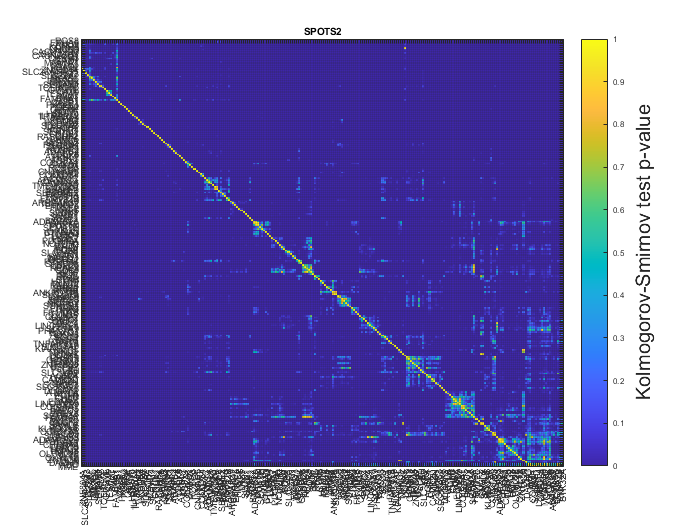

SPOTS.hexbin_size=20;
DissimilarityTest(SPOTS);

NearNeighbors(SPOTS,1)

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



**This tool I do not know what it does**

FindNeighbors_screen_randomization(SPOTS)

# Analysis of Cortex

We first use ROI_draw_onImage to get a ROI. We can also add a gene of interest in 3rd position in order to select on a density map

image_selected=1;
CORTEX_SPOTS=ROI_draw_onImage(SPOTS,image_selected); %{'MTOR'}
image_selected=2;
CORTEX_SPOTS2=ROI_draw_onImage(SPOTS,image_selected); %{'MTOR'}

CORTEX_SPOTS=MergeObjects(CORTEX_SPOTS,CORTEX_SPOTS2)

Working with cortex spots, we generate the gradient of genes. In this case, we have select the border of the gradient. From the spots defined, it will calculate the distance.

imagesel=1
SPOTS.limit=10000
gradients(SPOTS,imagesel);


Then, we generate bins, saving it in CORTEX_BINS. This Matisse Object contains the Bins in the cortex. Then we appy two things. First we apply the tsneRGB, to visualize bins

SPOTS.radius=100;
SPOTS.distance=100;
SPOTS.count_threshold=1;
BINS=OverlappingBins(SPOTS)

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



tsneRGB(BINS)

Then we perform clustering. We include 3 parameters. First the Matisse Object (CORTEX_BINS). The second parameters includes the number  of clusters generated. Finally we selecet the method. Wer can select 'hierarchical' or 'kmeans'.

BINS=Clustering(BINS,20,'hierarchical');


We then try to work with cells. For this, we fist segment nuclei and then we use the CellMap in the second function callded "define_cells" for creating the cells object

[CORTEX_SPOTS]= DAPI_segmentation(CORTEX_SPOTS)
[CORTEX_CELLS]= define_cells(CORTEX_SPOTS);

Run umap allows you to perfrom UMAP. Right now, we are only using the CORTEX_CELLS.UMAP_clustering parameter. We represent the cluster

[UM,n,CORTEX_CELLS.UMAP_clustering]=run_umap(CORTEX_CELLS.expressionmatrix);
CORTEX_CELLS.spotname=CORTEX_CELLS.UMAP_clustering';

figure
imshow(imresize(imread(CORTEX_CELLS.images{1}),1/CORTEX_CELLS.scale{1})*10)
hold on
gscatter(CORTEX_CELLS.location(:,1),CORTEX_CELLS.location(:,2),CORTEX_CELLS.spotname)


We can also perform normal clustering 

CORTEX_CELLS=Clustering(CORTEX_CELLS,20,'hierarchical');

**PCISEQ**

For PCISEQ we need to generate the gSet first. 

load E:\pciSeq\Data\AllSections\gSetCA1all.mat;
gSet.GeneExp=readmatrix('F:\HCA_09b_mouse_120genes\singleCellMatrix_2018.csv');
gSet.GeneExp;
gSet.GeneExp=gSet.GeneExp';
gSet.GeneExp=gSet.GeneExp(3:end,:);
gSet.GeneExp=gSet.GeneExp';
gSet.nGenes=size(gSet.GeneExp,1);
gSet.nCells=size(gSet.GeneExp,2);
%extrainfo=readtable('C:\Users\sergio.salas\Downloads\sample-annotations\sample_annotations.csv');
%gSet.CellInfo=[]
GENAME=readtable('F:\HCA_09b_mouse_120genes\gene_names_2018.csv');
gSet.GeneName=[GENAME.V1]
CENAME=readtable('F:\HCA_09b_mouse_120genes\sample_name_2018.csv');
gSet.CellName=[CENAME.sample_name]
CLASS=readtable('F:\HCA_09b_mouse_120genes\sample_name_2018.csv');
gSet.Class=[CLASS.cluster]


We then run PCISEQ, and save the output in a Matisse object (Cells object).

PCISEQ=pciseq(CORTEX2_SPOTS,gSet);

We then perform dissimilarity test, Near Neighbors analysis (Colocalization) and gradients for PCISEQ

PCISEQ.hexbin_size=1;
PCISEQ.count_threshold=1;
DissimilarityTest(PCISEQ)
NearNeighbors(PCISEQ,1)
PCISEQ.limit=12000;
gradients(PCISEQ,1);

# **CORTEX 2**

image_selected=1;
CORTEX2_SPOTS=ROI_draw_onImage(SPOTS,image_selected); %{'MTOR'}


Working with cortex Spots

imagesel=1
CORTEX2_SPOTS.limit=10000
gradients(CORTEX2_SPOTS,imagesel);


CORTEX2_SPOTS.radius=150;
CORTEX2_SPOTS.distance=70;
CORTEX2_BINS=OverlappingBins(CORTEX2_SPOTS)
tsneRGB(CORTEX2_BINS)
CORTEX2_BINS.images=CORTEX2_BINS.images{1}
CORTEX2_BINS=Clustering(CORTEX2_BINS,20,'hierarchical');

[CORTEX2_SPOTS]= DAPI_segmentation(CORTEX2_SPOTS)
[CORTEX2_CELLS]= define_cells(CORTEX2_SPOTS);

CORTEX2_CELLS.images=CORTEX2_CELLS.images{1}
[UMAPOUT,n,clusters_cortex]=run_umap(CORTEX2_CELLS.expressionmatrix);
CORTEX2_CELLS.spotname=clusters_cortex;

figure
imshow(imresize(imread(CORTEX2_CELLS.images{1}),1/CORTEX2_CELLS.scale{1})*10)
hold on
gscatter(CORTEX2_CELLS.location(:,1),CORTEX2_CELLS.location(:,2),CORTEX2_CELLS.spotname)

CORTEX2_CELLS.spotname=num2str(CORTEX2_CELLS.Clustering_ID)
[CORTEX_CELLS_REDUCED,CORR_PCA]=principal_components(CORTEX2_CELLS,1)


CORTEX2_CELLS.images=CORTEX2_CELLS.images{1};
CORTEX2_CELLS=Clustering(CORTEX2_CELLS,20,'hierarchical');

CORTEX_CELLS_REDUCED.colormap=jet(29);
CORTEX2_CELLS.colormap=jet(20)
heatmap_cluster(CORTEX2_CELLS);
CORTEX_CELLS.spotname=CORTEX_CELLS.spotname';
CORTEX_CELLS.images{1}=CORTEX_CELLS.images;
NearNeighbors(CORTEX2_SPOTS,1)

CORTEX2_SPOTS.hexbin_size=6;
CORTEX2_SPOTS.count_threshold=1;
DissimilarityTest(SPOTS);
CORTEX2_CELLS.spotname=CORTEX2_CELLS.Clustering_ID;
CORTEX2_CELLS.limit=8000;
gradients(CORTEX2_CELLS,1);


Gradients

CELLS.spotname=clusters;
imagesel=1
gradients(CELLS,imagesel);

Enriched genes

type1=19;
type2=14;
imagesel=1;
fa=CORTEX2_CELLS.images
CORTEX2_CELLS.images={};
CORTEX2_CELLS.images{1}=fa
GLOBAL=enrichedgenes(CORTEX2_CELLS,imagesel,9,19)

Near Neighbors

NearNeighbors(CELLS,imagesel);

ENVIROSPOTS=SpotEnvBin(SPOTS)



## Other section


[COROVE]=ROI_draw_onImage(SPOTS,1);

Velocity(COROVE);